clear, clc, close all
interval_x = [-10 10];
interval_y = [-10 10];
x = linspace(interval_x(1), interval_x(2), 100);
y = linspace(interval_y(1), interval_y(2), 100);
[meshx, meshy] = meshgrid(x, y);

X = [meshx(:), meshy(:)]';

neuro = Neuron;
neuro = neuro.init_(2);

neuro = neuro.forward_propagation(X);

plot_output = reshape(neuro.output, [100, 100]);
% plot_output(plot_output < 0.5) = 0;
% plot_output(plot_output >= 0.5) = 1;


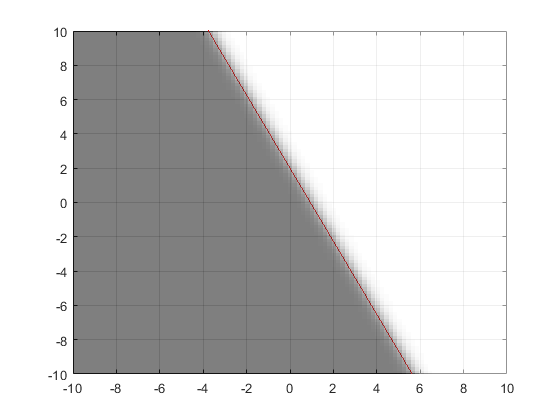

f = figure;
ax = axes(f); hold on; grid on; box on;
colormap('gray')
ax.XLim = interval_x;
ax.YLim = interval_y;
h = surface(ax, x, y, plot_output);
h.FaceAlpha = 0.5;
h.EdgeAlpha = 0;
neuro.plotNeuroLine(ax,'r');

neuros(1) = Neuron;
neuros(1) = neuros(1).init_(2);
neuros(2) = Neuron;
neuros(2) = neuros(2).init_(2);
neuros(3) = Neuron;
neuros(3) = neuros(2).init_(2);

neuros(1) = neuros(1).forward_propagation(X);
neuros(2) = neuros(2).forward_propagation(X);
neuros(3) = neuros(3).forward_propagation([neuros(1).output; neuros(2).output]);

plot_output = reshape(neuros(3).output, [100, 100]);
% plot_output(plot_output < 0.5) = 0;
% plot_output(plot_output >= 0.5) = 1;


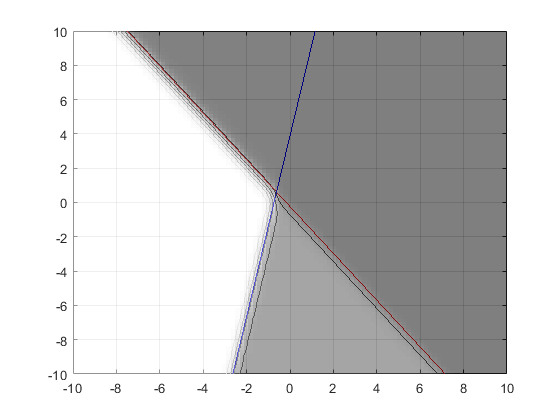

f = figure;
ax = axes(f); hold on; grid on; box on;
colormap('gray')
ax.XLim = interval_x;
ax.YLim = interval_y;
hSurface = surface(ax, x, y, plot_output);
contour(ax, x, y, plot_output);
hSurface.FaceAlpha = 0.5;
hSurface.EdgeAlpha = 0;
neuros(1).plotNeuroLine(ax,'r');
neuros(2).plotNeuroLine(ax,'b');

neuros(1) = Neuron;
neuros(1) = neuros(1).init_(2);
neuros(2) = Neuron;
neuros(2) = neuros(2).init_(2);
neuros(3) = Neuron;
neuros(3) = neuros(3).init_(2);
neuros(4) = Neuron;
neuros(4) = neuros(4).init_(2);
neuros(5) = Neuron;
neuros(5) = neuros(5).init_(4);

neuros(1) = neuros(1).forward_propagation(X);
neuros(2) = neuros(2).forward_propagation(X);
neuros(3) = neuros(3).forward_propagation([neuros(1).output; neuros(2).output, neuros(3).output; neuros(4).output]);

plot_output = reshape(neuros(3).output, [100, 100]);
% plot_output(plot_output < 0.5) = 0;
% plot_output(plot_output >= 0.5) = 1;


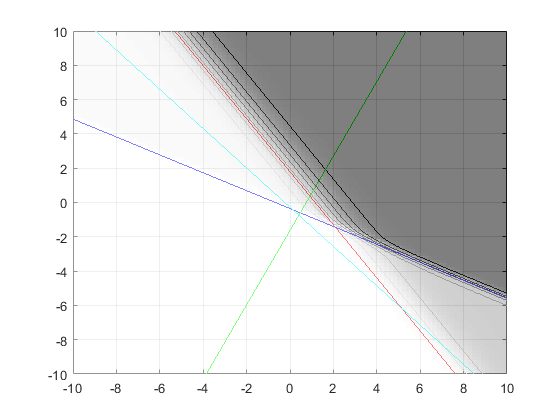

f = figure;
ax = axes(f); hold on; grid on; box on;
colormap('gray')
ax.XLim = interval_x;
ax.YLim = interval_y;
hSurface = surface(ax, x, y, plot_output);
h = contour(ax, x, y, plot_output);
hSurface.FaceAlpha = 0.5;
hSurface.EdgeAlpha = 0;
neuros(1).plotNeuroLine(ax,'r');
neuros(2).plotNeuroLine(ax,'b');
neuros(3).plotNeuroLine(ax,'g');
neuros(4).plotNeuroLine(ax,'c');

layer = Layer;
layer = layer.init_(1,2);
layer = layer.forward_propagation(X);
plot_output = reshape(layer.output, [100, 100]);

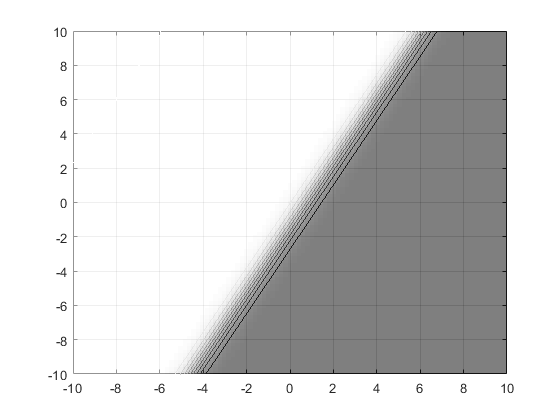

f = figure;
ax = axes(f); hold on; grid on; box on;
colormap('gray')
ax.XLim = interval_x;
ax.YLim = interval_y;
hSurface = surface(ax, x, y, plot_output);
h = contour(ax, x, y, plot_output);
hSurface.FaceAlpha = 0.5;
hSurface.EdgeAlpha = 0;

layers(16) = Layer;
output_layers(16) = Layer;
for i = 1:length(layers)
    layers(i) = layers(i).init_(i,2);
    output_layers(i) = output_layers(i).init_(1,i);
    
    layers(i) = layers(i).forward_propagation(X);
    output_layers(i) = output_layers(i).forward_propagation(layers(i).output);
    plot_outputs(:,:,i) = reshape(output_layers(i).output, [100, 100, 1]);
end

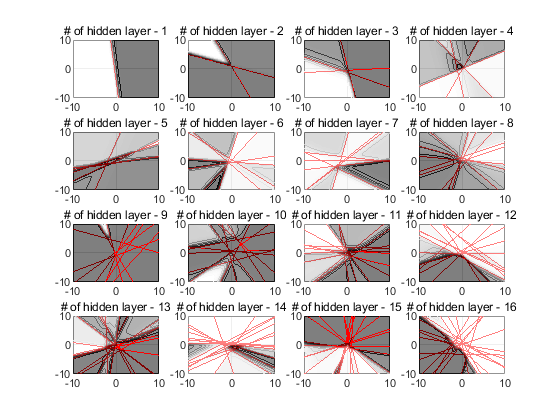

f = figure;
colormap('gray')
for i = 1:length(layers)
    subplot(4,4,i); 
    ax = gca; hold on; grid on; box on;
    title(sprintf("# of hidden layer - %d", i));
    ax.XLim = interval_x;
    ax.YLim = interval_y;
    hSurface = surface(ax, x, y, plot_outputs(:,:,i));
    h = contour(ax, x, y, plot_outputs(:,:,i));
    layers(i).plotLayerLines(ax, 'r');
    hSurface.FaceAlpha = 0.5;
    hSurface.EdgeAlpha = 0;
end